# Kalman Filter Workshop Exercise #2: Extended Kalman Filters

In this exercise, you will design an extended Kalman filter to estimate spacecraft attitude. 

## Simulating the Spacecraft

In this exercise, you will use this Simulink model (shown below) that contains the [Attitude Dynamics](https://www.mathworks.com/help/aeroblks/attitudedynamics.html) block from Aerospace Blockset to simulate our spacecraft's dynamics. The spacecraft starts with an initial attitude and rate, after which it rotates without any external forces acting on it (torque-free motion). 

The model also includes an angular rate sensor model (gyro) and an attitude sensor model (star tracker). The gyro model runs at a rate of 100 Hz and includes random white noise. The star tracker model also includes random white noise, and has a sampling interval that's controlled by the "time_between_measurements" variable below, initially set to 5 Hz.

The model has 3 different methods of estimating the spacecraft's attitude from this sensor data, implemented with a [variant subsystem](https://www.mathworks.com/help/simulink/slref/variantsubsystemvariantmodelvariantassemblysubsystem.html).

- Dead reckoning (using simulated sensor data from the gyro)

- Dead reckoning with periodic attitude updates (using simulated sensor data from the gyro and star tracker)

- An extended Kalman filter (using simulated sensor data from the gyro and star tracker)

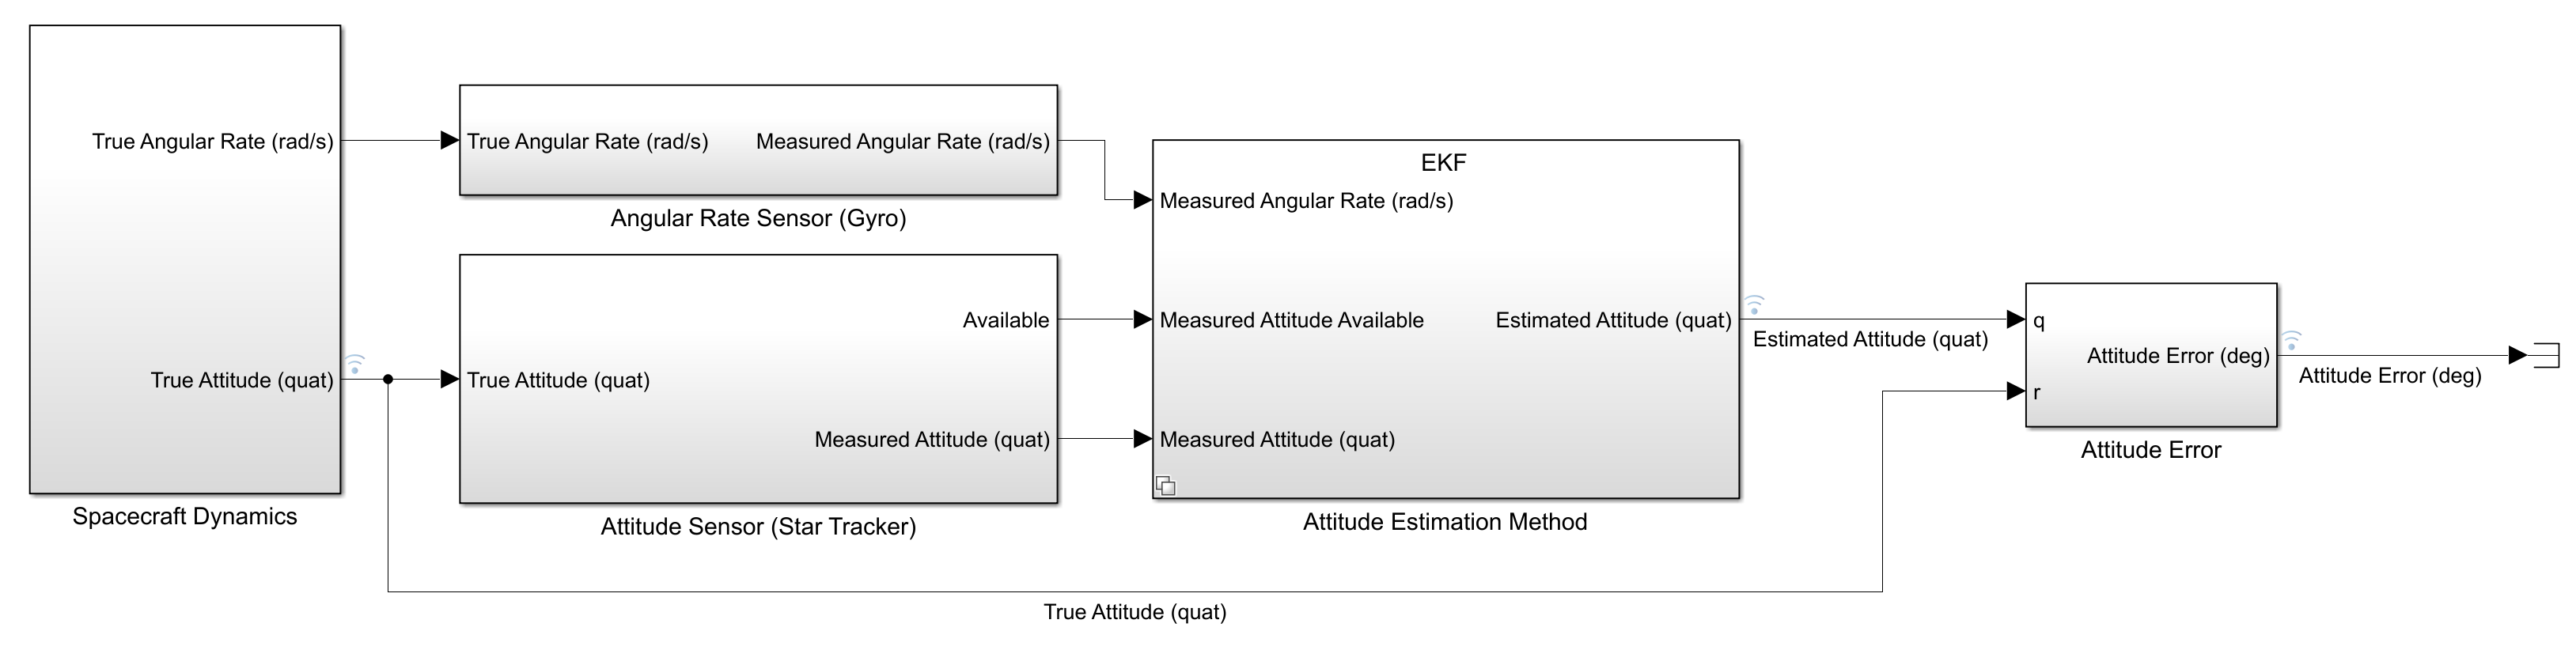

Uncomment the below line of code to open the supplemental live script for more details on the model.

% open EKFSupplemental.mlx

First, **run this section** to specify parameters for the model and open the model.

% Clear workspace from previous exercise
clear;

% Simulation parameters
tstop = 50;
dt = 0.01;

% Spacecraft parameters
inertia_tensor_kg_m2 = [1 0 0; 
                        0 2 0; 
                        0 0 3];
initial_attitude_quat = [1 0 0 0];
initial_rate_radps = [0.05 .05 0];

% Angular rate sensor
gyro_noise = 1e-5; %#ok, used in model

% Attitude sensor 
star_tracker_noise = 1e-6;
time_between_measurements = .2;

% Choose a variant for the attitude estimation
ad_method = 1; %#ok, used in model

% Open model
open_system spacecraft_model

**Run this section** to run the simulation using the [`sim`](https://www.mathworks.com/help/simulink/slref/sim.html) function and observe the attitude of the spacecraft over time. 

% Run model
out = sim("spacecraft_model");

% Plot orientation
figure;
[truequats_ts, estquats_ts]= plotOrientation(out,100,plotTrue=true); 

## Estimate Attitude with Dead Reckoning (Gyro Only)

Dead reckoning is a method used to estimate a spacecraft’s orientation by calculating the cumulative effect of its angular velocity over time. In our simulation, we begin with a perfect initial estimate of the spacecraft’s attitude. Then we propagate the estimated quaternion at each time step using the angular rate in three body axes measured by the gyro. This is implemented in the "Deadreckon" MATLAB function block.

**Run this section** to run the simulation and plot the attitude and error over time using this estimation approach.

% Choose the dead reckon variant for the attitude estimation variant subsystem
ad_method = 1; %#ok, used in model

% Run model
out = sim("spacecraft_model");

% Plot estimation error
dr_atterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
figure; plot(dr_atterror_ts); 
ylabel('Degrees'); title('Absolute Attitude Error'); legend('Dead Reckon');
% Plot orientation
figure;
[dr_truequats_ts, dr_estquats_ts]= plotOrientation(out,100,plotTrue=true,plotEst=true);

Notice the error gradually increases over time - this divergence is caused by angle random walk, a phenomenon that occurs when integrating a signal with noise.  

### Activity 1: Study Effect of Noise on Attitude Estimation Error

An obvious way to increase the accuracy of dead reckoning is to use gyroscopes with lower noise levels. **Use the below drop-down** to set the gyro noise to different values and observe how the error of the attitude estimation changes. The more noise, the higher the error.

gyro_noise = 1e-04;

% Run model
out = sim("spacecraft_model");

% Plot estimation error
dr_newatterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
figure;  plot(dr_atterror_ts); 
hold on; plot(dr_newatterror_ts); hold off;
ylabel('Degrees'); title('Absolute Attitude Error'); 
legend("Noise = 1e-05","Noise = "+compose("%.0e",gyro_noise));

Using a gyroscope with a lower noise level is not always practical, so instead, we can periodically adjust the estimated attitude with an absolute measurement from another sensor, like our star tracker. We will implement this adjustment in the next section.

## Estimate Attitude with Dead Reckoning and Star Tracker Updates

To mitigate the attitude drift that occurs with dead reckoning, one effective strategy is to rely on periodic updates from the star tracker. When star tracker data is available, we can reset the estimated attitude to match the star tracker’s readings, essentially treating the star tracker as the definitive source for attitude information. In the intervals between star tracker updates, we continue to estimate the spacecraft’s orientation using gyro data and the dead reckoning approach. 

**Run this section** to run the simulation and plot the attitude and error over time using this estimation approach.

% Choose the dead reckon variant with star tracker updates for the attitude estimation variant subsystem
ad_method = 2; %#ok, used in model

% Reset parameters changed by activities
gyro_noise = 1e-5; %#ok, used in model

% Run model
out = sim("spacecraft_model");

% Plot estimation error
drst_atterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
figure; plot(dr_atterror_ts); 
hold on; plot(drst_atterror_ts); hold off;
ylabel('Degrees'); title('Absolute Attitude Error'); 
legend("Dead Reckon",...
       "Dead Reckon + ST, "+compose("%.1f",time_between_measurements)+"s between updates");

% Plot orientation
figure;
[drst_truequats_ts, drst_estquats_ts]= plotOrientation(out,100,plotTrue=true,plotEst=true);

With this method, the absolute attitude error remains approximately equal to the star tracker’s error. This is because the intervals between star tracker measurements are short enough that they don’t allow significant drift due to the gyro’s angle random walk. Consequently, our attitude estimation will never surpass the accuracy provided by the star tracker. Each time the star tracker offers a reading, our estimated attitude abruptly aligns with it.

### Activity 2: Explore Impact of Star Tracker Measurement Frequency

In this activity, we change the frequency of our star tracker measurements to see how it effects the error of our attitude estimate. **Use the below slider** to run our simulation with different star tracker frequencies. 

time_between_measurements = 5;

% Run model
out = sim("spacecraft_model");

% Plot estimation error
drst_newatterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
figure; plot(dr_atterror_ts); 
hold on; plot(drst_newatterror_ts); hold off;
ylabel('Degrees'); title('Absolute Attitude Error'); 
legend("Dead Reckon",...
       "Dead Reckon + ST, "+compose("%.1f",time_between_measurements)+"s between updates");

By increasing the time between updates, we can see how the overall estimate will abruptly align with the star tracker estimate at each new measurement - even if the gyroscopic data suggests that the spacecraft rotated less during that interval. 

Consider a scenario where the star tracker's measurement is within 1 degree of the true attitude at one moment, and then within 3 degrees a few seconds later, indicating an apparent 2-degree rotation. However, if the gyro-based dead reckoning indicates only a 0.5-degree rotation in the same timeframe, it raises the question: which estimate is more reliable? 

The answer depends on their respective uncertainties, quantified as covariances. If dead reckoning is more precise over short periods compared to the star tracker, it's reasonable to partially discount the star tracker's measurement, favoring an estimated attitude that lies between the dead reckoning prediction and the star tracker's reading. This intermediate estimation is precisely what an Extended Kalman Filter (EKF) accomplishes, which is our focus in the next section.

## Estimate Attitude with Extended Kalman Filter

In this model, we implement an additive extended Kalman filter with the EKF block from Control System Toolbox. 

An EKF is comprised of two steps:

- A prediction step, where a model propagates the system state forward in time

- An update step, where the estimated state is adjusted based on a new measurement

**Run this section **to assign values to the variables used in the EKF block and run the simulation.

*Prediction Step*

In this example, our prediction step will use the same model we used for dead reckoning. The state transition function encapsulates the prediction model; we reference this function in the EKF block. Uncomment the below line to see the state transition function: 

% open stateTransitionFnc

We also need to specify the process covariance to express our confidence in the model's accuracy. 

pc_exponent =-8.7;
process_covariance = eye(4)*exp(pc_exponent); %#ok, used in model

*Update Step*

In this example, we adjust our estimated state based on measurements from the star tracker. The measurement function takes these measurements and processes them so they can be used by the EKF block. In this example, the measurement function is straightforward because the star tracker directly measures the state in question - it provides a quaternion. If our sensor measured attitude in a different coordinate system or required additional processing, we would capture that within the measurement function. Uncomment the below line to see the measurement function: 

% open measurementFnc

We also need to specify the measurement covariance, which represents our confidence in the accuracy of the star tracker measurements. 

measurement_covariance = eye(4);

*Filter Initialization*

For the EKF, we must provide an initial state estimate and define an initial state covariance. If the system's initial state is unknown, you can select an arbitrary initial orientation and assign a high initial covariance to reflect the low confidence in this guess. On the other hand, if a reliable initial state is available, then the initial covariance can be set lower to express greater confidence in that initial estimate. This is the approach taken in our example.

initial_state = [1 0 0 0];
initial_covariance = 1e-12;

*Simulate*

Run the simulation and plot the attitude and error over time using this estimation approach.

% Choose the EKF variant for the attitude estimation variant subsystem
ad_method = 3; 

% Reset parameters changed by activities
gyro_noise = 1e-5;
time_between_measurements = .2;

% Run model
out = sim("spacecraft_model");

% Plot estimation error
ekf_atterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
%figure; plot(dr_atterror_ts); 
%hold on; plot(drst_atterror_ts);
plot(ekf_atterror_ts,'k','LineWidth',3); hold off;
ylabel('Degrees'); title('Absolute Attitude Error'); 
legend("Dead Reckon","Dead Reckon + ST","EKF, pc exponent = "+compose("%.1f",pc_exponent));

% Plot orientation
figure;
[ekf_truequats_ts, ekf_estquats_ts]= plotOrientation(out,100,plotTrue=true,plotEst=true);

### Activity 3a: Manually Explore Effect of Process Covariance 

Determining the process covariance can be challenging as uncertainties can stem from both an imperfect understanding of the system dynamics and unaccounted external disturbances. This is particularly true for space applications where testing in the actual environment is difficult.

**Use the below slider** to the run the simulation with different process covariances and observe its effect on the estimated state. What's the best value for our process covariance in this example?

pc_exponent =-10.9;
process_covariance = eye(4)*exp(pc_exponent); %#ok, used in model

% Run model
out = sim("spacecraft_model");

% Plot estimation error
ekf_newatterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
figure; plot(dr_atterror_ts); 
hold on; plot(drst_atterror_ts);
plot(ekf_newatterror_ts,'k','LineWidth',3); hold off;
ylabel('Degrees'); title('Absolute Attitude Error'); 
legend("Dead Reckon","Dead Reckon + ST","EKF, pc exponent = "+compose("%.1f",pc_exponent));

### Activity 3b: Use Optimization to Determine Process Covariance

Instead of manually changing the value for `pc_exponent` in hopes of finding the best result, we can use optimization to determine the optimum value. The below gif shows how a range of values for `pc_exponent` affects the attitude error as well as some statistical measurements we may want to use as a loss function. To see how we made this gif, open the "EKF_GIF_creation" live script.

% open EKF_GIF_Creation.mlx

 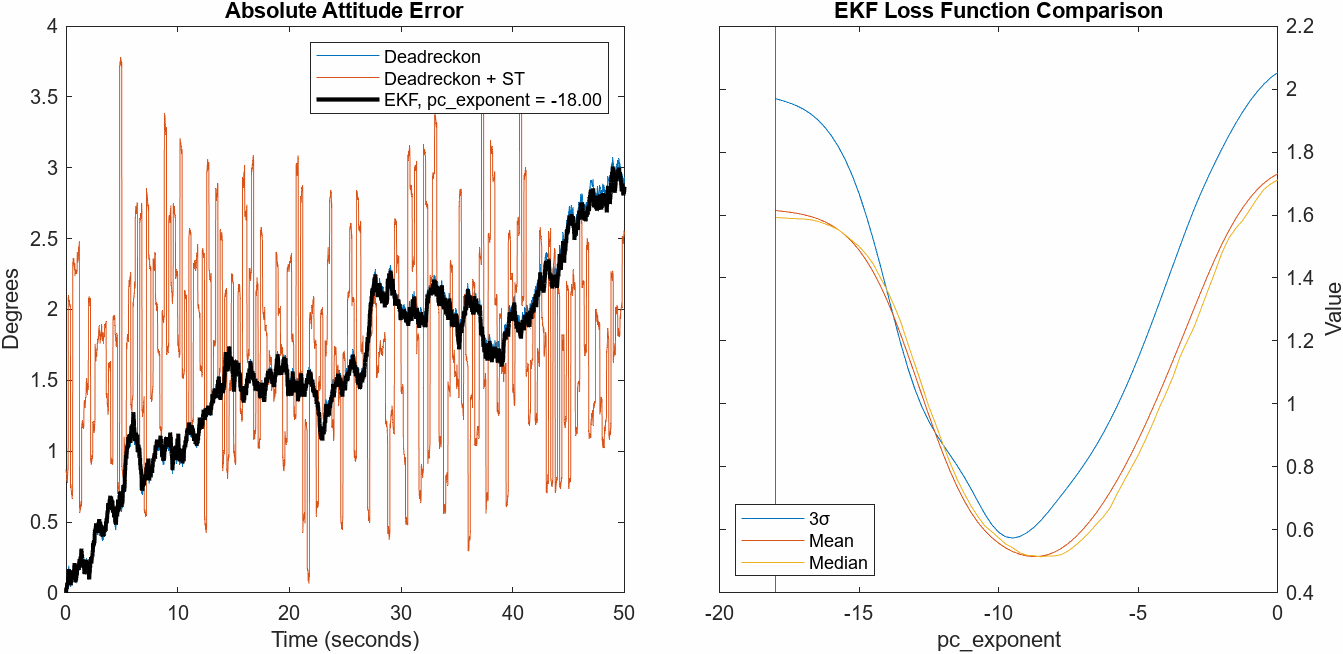

We'll use the [Optimize Live Task](https://www.mathworks.com/help/matlab/math/optimize-live-editor-matlab.html) to set up and run this optimization problem. 

Before setting up this live task, we'll need to create a loss function. In this example, we chose to use standard deviation. 

open lossFunction.m

You can change the loss function as needed to reflect your specific needs. Some considerations before performing the optimization are:

- What parameters are to be optimized?

- What loss function, solver, and parameters are appropriate for the optimization?

- What tolerances allow the optimization to converge without taking too much time? 0.01, 0.001, etc.

- What portion of the signal do we want to optimize? 0-50 seconds, 10-25 seconds, etc.

**Run the live task** to run the optimization. How close is the optimizer's answer to the answer you found manually in Activity 3a? 

% Set nondefault solver options
options = optimset("TolX",0.01,"Display","iter");

% Solve
[solution,objectiveValue] = fminbnd(@lossFunction,-16,0,options);

% Clear variables
clearvars options

Once the optimization converges to a solution, **run this section** to run the simulation with the new process covariance value.

% Run model
pc_exponent = solution;
process_covariance = eye(4)*exp(pc_exponent);
out = sim("spacecraft_model");

% Plot estimation error
ekf_newatterror_ts = out.logsout.getElement("Attitude Error (deg)").Values;
figure; plot(dr_atterror_ts); 
hold on; plot(drst_atterror_ts);
plot(ekf_newatterror_ts,'k','LineWidth',3); hold off;
ylabel('Degrees'); title('Absolute Attitude Error'); 
legend("Dead Reckon","Dead Reckon + ST","EKF, pc exponent = "+compose("%.1f",pc_exponent));
% Plot orientation
figure;
[ekf_newtruequats_ts, ekf_newestquats_ts]= plotOrientation(out,100,plotTrue=true,plotEst=true);